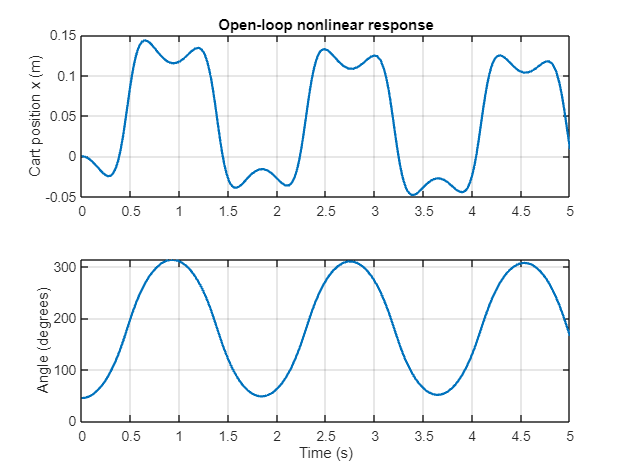


clear; clc; close all;

%% 1. Physical parameters (ILLUSTRATIVE - replace these)
p.M = 0.5;       % cart mass (kg)
p.m = 0.2;       % pendulum mass (kg)
p.l = 0.3;       % pivot-to-COM distance (m)
p.J = 0.006;     % pendulum inertia about COM (kg*m^2)
p.g = 9.8;      % gravity (m/s^2)
p.b = 0.1;       % cart viscous damping (N*s/m)
p.c = 0.0;       % pivot viscous damping (N*m*s/rad)

p.Jt = p.J + p.m*p.l^2;

%% 2. Initial condition
% State: [cart position; cart velocity; angle; angular velocity]
z0 = [0; 0; deg2rad(45); 0];

tspan = [0 5];

%% 3. Open-loop simulation: u = 0
[t_open, z_open] = ode45( ...
    @(t,z) cartpoleNL(z, 0, p), tspan, z0);

%% 4. Plot the response
figure;
subplot(2,1,1);
plot(t_open, z_open(:,1), 'LineWidth', 1.5);
grid on;
ylabel('Cart position x (m)');
title('Open-loop nonlinear response');

subplot(2,1,2);
plot(t_open, rad2deg(z_open(:,3)), 'LineWidth', 1.5);
grid on;
ylabel('Angle (degrees)');
xlabel('Time (s)');

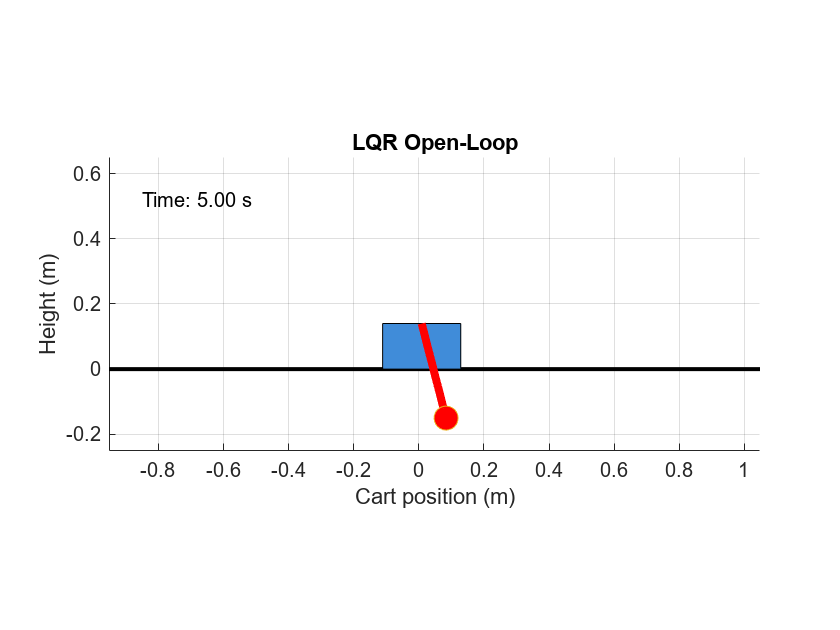

animateCartPole(t_open, z_open, p.l, 'LQR Open-Loop');

%fixed point
z_fixed = zeros(4,1);
u_fixed = 0;


syms x xdot theta omega u real
z_sym = [x; xdot; theta; omega];
dz_sym = cartpoleNL(z_sym, u, p); 

% Jacobians
A_sym = jacobian(dz_sym, z_sym)

$$A\_sym = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & \frac{2}{\sigma_{1}} & -\frac{6\,\omega^{2}\,\cos\left(\theta \right)-147\,{\cos\left(\theta \right)}^{2}+147\,{\sin\left(\theta \right)}^{2}}{5\,\sigma_{1}}-\frac{6\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(6\,\sin\left(\theta \right)\,\omega^{2}+100\,u-10\,\mathrm{xdot}-147\,\cos\left(\theta \right)\,\sin\left(\theta \right)\right)}{5\,{\sigma_{1}}^{2}} & -\frac{12\,\omega \,\sin\left(\theta \right)}{5\,\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & -\frac{5\,\cos\left(\theta \right)}{\sigma_{1}} & -\frac{343\,\cos\left(\theta \right)-3\,\omega^{2}\,{\cos\left(\theta \right)}^{2}+3\,\omega^{2}\,{\sin\left(\theta \right)}^{2}+50\,u\,\sin\left(\theta \right)-5\,\mathrm{xdot}\,\sin\left(\theta \right)}{\sigma_{1}}-\frac{6\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(-3\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,\omega^{2}+343\,\sin\left(\theta \right)-50\,u\,\cos\left(\theta \right)+5\,\mathrm{xdot}\,\cos\left(\theta \right)\right)}{{\sigma_{1}}^{2}} & \frac{6\,\omega \,\cos\left(\theta \right)\,\sin\left(\theta \right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,{\cos\left(\theta \right)}^{2}-14 \end{array}$$

B_sym = jacobian(dz_sym, u)

$$B\_sym = \left(\begin{array}{c} 0\\ -\frac{20}{3\,{\cos\left(\theta \right)}^{2}-14}\\ 0\\ \frac{50\,\cos\left(\theta \right)}{3\,{\cos\left(\theta \right)}^{2}-14} \end{array}\right)$$


% Values of jacobians for those fixed points
A = double(subs(A_sym, [z_sym; u], [z_fixed; u_fixed]));
B = double(subs(B_sym, [z_sym; u], [z_fixed; u_fixed]));

disp('A ='); disp(A);

A =
         0    1.0000         0         0
         0   -0.1818   -2.6727         0
         0         0         0    1.0000
         0    0.4545   31.1818         0



disp('B ='); disp(B);

B =
         0
    1.8182
         0
   -4.5455



lambda_open= eig(A)

lambda_open =          0
   -0.1428
   -5.6041
    5.5651


%is the matrix controllable?
% prerequisite for implementing LQR
rank(ctrb(A, B))

ans = 4


%% 7. LQR design

Q = diag([1/5^2, 1/2^2, 1/0.1^2, 1/1.5^2]);
R = 1/100^2;

% Calculate optimal state-feedback gain
K = lqr(A, B, Q, R);

disp('LQR gain K =');

LQR gain K =


disp(K);

   1.0e+03 *

   -0.0200   -0.0831   -1.0817   -0.1061




%% 8. Verify closed-loop poles
lambda_closed = eig(A - B*K)

lambda_closed = 1.0e+02 *

  -3.1614 + 0.0000i
  -0.1451 + 0.0000i
  -0.0040 + 0.0019i
  -0.0040 - 0.0019i


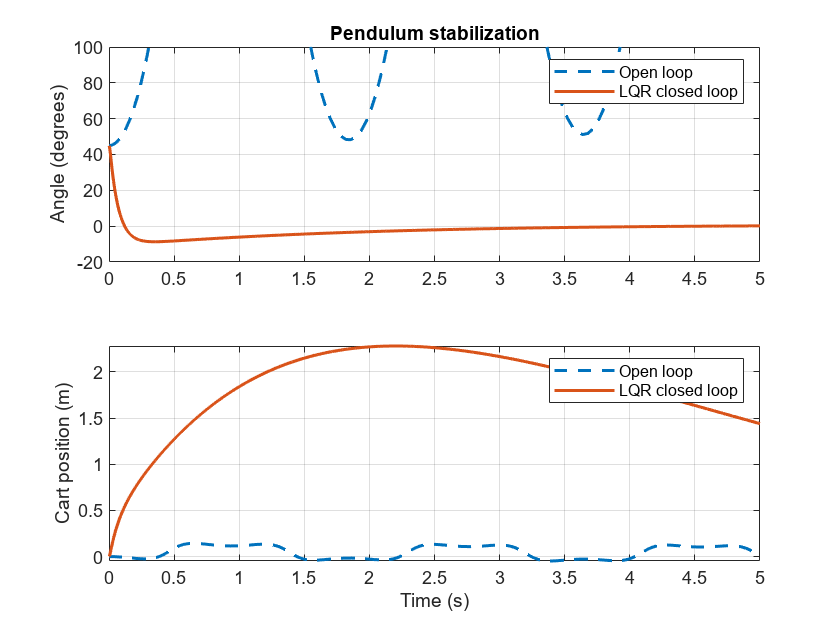


%% 9. Closed-loop nonlinear simulation

[t_cl, z_cl] = ode45( ...
    @(t,z) cartpoleNL(z, -K*z, p), tspan, z0);

% Reconstruct the control force
u_cl = zeros(length(t_cl),1);

for i = 1:length(t_cl)
    u_cl(i) = -K*z_cl(i,:)';
end

%% 10. Compare open-loop and closed-loop responses

figure;

subplot(2,1,1);
plot(t_open, rad2deg(z_open(:,3)),'--','LineWidth', 1.5);
hold on;
plot(t_cl, rad2deg(z_cl(:,3)),'LineWidth', 1.5);
grid on;
ylabel('Angle (degrees)');
legend('Open loop','LQR closed loop');
title('Pendulum stabilization');
ylim([-20, 100])

subplot(2,1,2);
plot(t_open, z_open(:,1),'--', 'LineWidth', 1.5);
hold on;
plot(t_cl, z_cl(:,1), 'LineWidth', 1.5);
grid on;
ylabel('Cart position (m)');
xlabel('Time (s)');
legend('Open loop','LQR closed loop');

subplot(2,1,2)

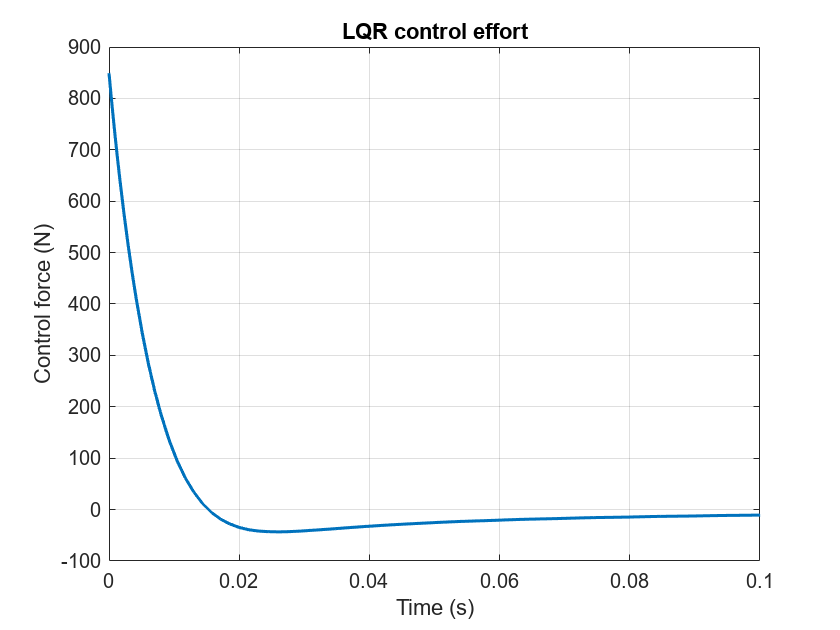



figure;
plot(t_cl, u_cl, 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Control force (N)');
title('LQR control effort');
xlim([0.00 0.1])


fprintf('Peak absolute force = %.3f N\n', max(abs(u_cl)));

Peak absolute force = 849.596 N


fprintf('Final angle = %.5f degrees\n', ...
    rad2deg(z_cl(end,3)));

Final angle = 0.15771 degrees


fprintf('Final cart position = %.5f m\n', z_cl(end,1));

Final cart position = 1.43988 m


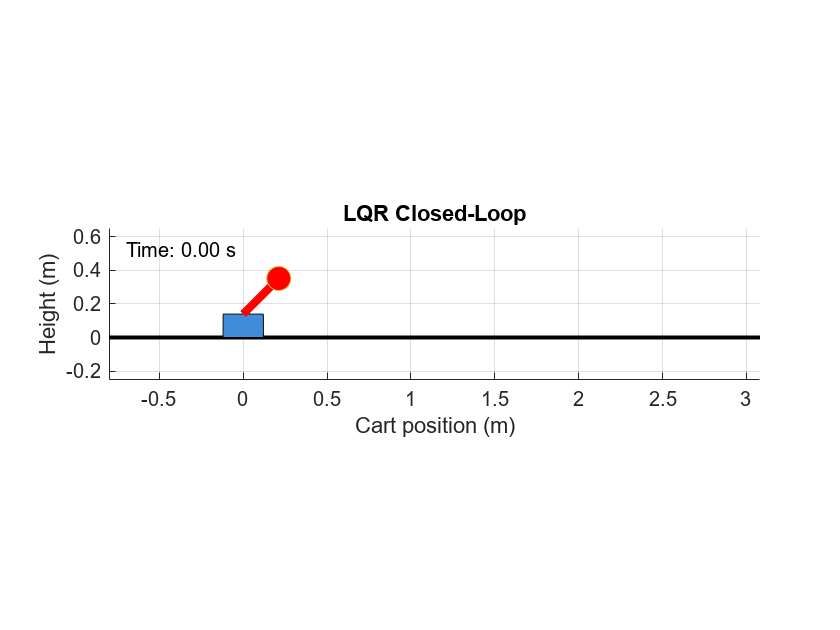



animateCartPole(t_cl, z_cl, p.l, 'LQR Closed-Loop');

function dz = cartpoleNL(z, u, p) % heart of the problem

    % State variables
    x     = z(1);
    xdot  = z(2); %vel
    theta = z(3);
    omega = z(4); %ang vel

    % Mass/inertia matrix
    H = [p.M + p.m, p.m*p.l*cos(theta);
         p.m*p.l*cos(theta), p.Jt];

    % Right-hand side of the coupled equations
    rhs = [u - p.b*xdot ...
              + p.m*p.l*omega^2*sin(theta);
           p.m*p.g*p.l*sin(theta) - p.c*omega]; % corliosis force 
% and force due to potential energy ie C(q, q') and K(q) are defined here 

    % Solve for cart and angular acceleration
    acc = H \ rhs;%in MATLAB '\' means inverse is on the left, '/' means on the right

    xddot = acc(1);
    thetaddot  = acc(2);

    % First-order state-space equations
    dz = [xdot;
          xddot;
          omega;
          thetaddot];
end

function animateCartPole(t, z, L, animationTitle)

    % Drawing dimensions
    cartW = 0.24;
    cartH = 0.14;
    fps = 40;

    % Interpolate trajectory for smoother animation
    t_frame = (t(1):1/fps:t(end))';

    if t_frame(end) < t(end)
        t_frame(end+1) = t(end);
    end

    z_frame = interp1(t, z, t_frame, 'pchip');

    % Fixed viewing window
    xmin = min(z(:,1)) - 0.8;
    xmax = max(z(:,1)) + 0.8;

    if xmax - xmin < 2
        midpoint = (xmin + xmax)/2;
        xmin = midpoint - 1;
        xmax = midpoint + 1;
    end

    % Set up figure
    figure('Color', 'w');
    hold on;
    axis equal;
    xlim([xmin xmax]);
    ylim([-0.25 L + 0.35]);
    grid on;

    xlabel('Cart position (m)');
    ylabel('Height (m)');
    title(animationTitle);

    plot([xmin xmax], [0 0], 'k-', 'LineWidth', 2);

    % Initial state: z = [x; x_dot; theta; theta_dot]
    xc = z_frame(1,1);
    theta = z_frame(1,3);

    xp = xc + L*sin(theta);
    yp = cartH + L*cos(theta);

    cart = patch( ...
        xc + [-cartW/2 cartW/2 cartW/2 -cartW/2], ...
        [0 0 cartH cartH], ...
        [0.25 0.55 0.85]);

    rod = plot([xc xp], [cartH yp], ...
        'r-', 'LineWidth', 4);

    bob = plot(xp, yp, 'o', ...
        'MarkerSize', 12, 'MarkerFaceColor', 'r');

    timeText = text(xmin + 0.1, L + 0.22, '');

    % Animation loop
    for k = 1:length(t_frame)

        xc = z_frame(k,1);
        theta = z_frame(k,3);

        xp = xc + L*sin(theta);
        yp = cartH + L*cos(theta);

        set(cart, 'XData', ...
            xc + [-cartW/2 cartW/2 cartW/2 -cartW/2]);

        set(rod, 'XData', [xc xp], ...
                 'YData', [cartH yp]);

        set(bob, 'XData', xp, 'YData', yp);

        set(timeText, 'String', ...
            sprintf('Time: %.2f s', t_frame(k)));

        drawnow;
    end
end
